# Conductive Scaffold FEA

## Intro

This script is intended to produce electrostatic plots for simple geometries

clear
clc
clf
set(0,'DefaultAxesFontSize',15,'defaultaxeslinewidth',2,...
    'defaultlinelinewidth',5,'defaultpatchlinewidth',1.5)

## Import the Geometry

### Define Material Geometry

The geometry is comprised of a conductive mesh within a finite volume defined by a cube. This geometry for the air is initialized and stored as gmAir. This is done first so that the geometry of the conductive mesh can fit inside the volume when it is then centered on the mesh. 

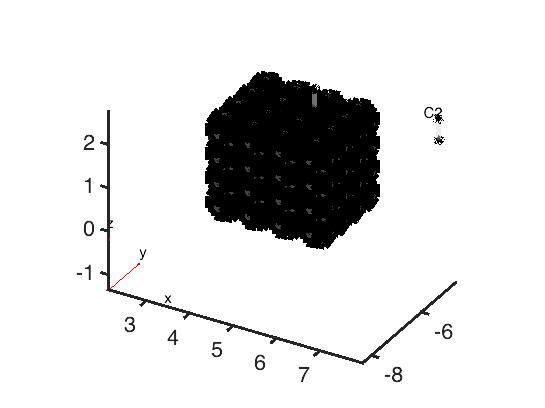

% Select the model and assign to gmModel

%Geom_Import    = importGeometry('Triangle 2 Electrode (2).stl');
Geom_Import    = importGeometry('125 3D Hema 2 Electrode (1).stl');

%Circle   = importGeometry('Basic 30x30mm Square.stl');
%Circle   = importGeometry('Basic 42x42mm Triangle.stl');
%Circle   = importGeometry('Basic Star.stl');
%Circle    = importGeometry('Fluid + Star combo.stl');

pdegplot(Geom_Import,'CellLabels','on','FaceAlpha',0.3);

### Define Fluid Volume

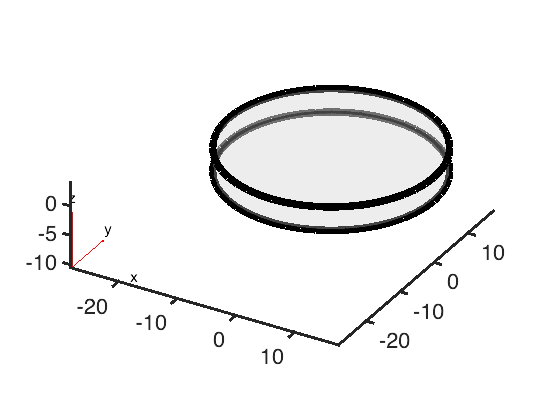

%First plot geometry and adjust the volume of the container of fluid then incorporate the
%geometry

gmFluid = multicylinder(17.5,4);
pdegplot(gmFluid,'FaceAlpha',0.3);

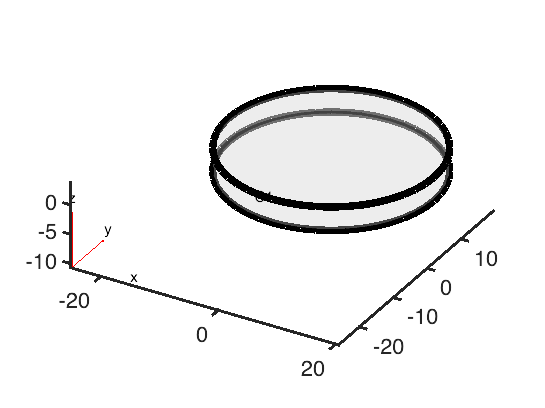


gmFluid.translate([3,2,-.2]);
pdegplot(gmFluid,'CellLabels','on','FaceAlpha',0.3);

pdegplot(Geom_Import,'CellLabels','on','FaceAlpha',0.3);

### Combine Both Geometries

%Ensure that the volume gmAir is the first input
gmModel = addCell(gmFluid,Geom_Import);
gmModel = scale(gmModel,.001); %scaled from mm to m

### Initial Plot of Loaded Geometry

Change the FaceAlpa input in pdegplot to better view the face and edge lables of the geometry.

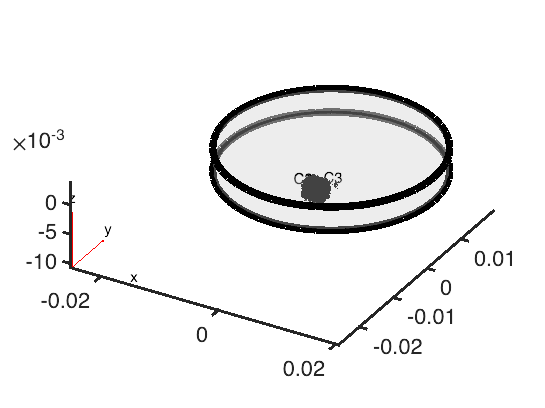

pdegplot(gmModel,'CellLabels','on','FaceAlpha',.3);

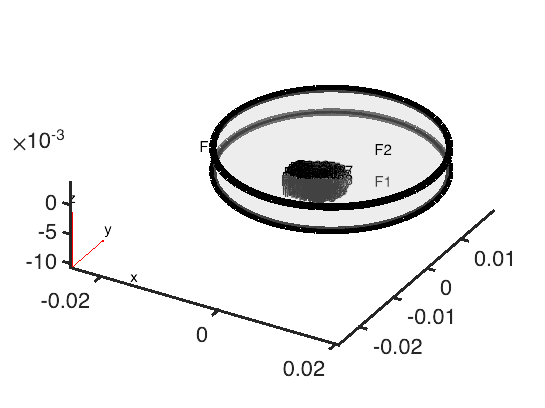

pdegplot(gmModel,'FaceLabels','on','FaceAlpha',.3);

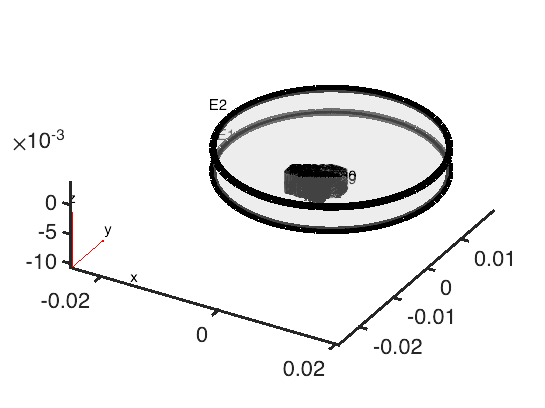

pdegplot(gmModel,'EdgeLabels','on','FaceAlpha',.3);

### Assign The Geomtery to the Model

The defined geometry becomes set to the model handle. The model is created and defined as Estat_model which is also an N # of equation elliptic model. 

Estat_model = createpde("electromagnetic","electrostatic");
Estat_model.Geometry = gmModel;

## Create the Mesh

From this we can generate a mesh where the fineness is defined by Hmin value, set at .35 for the lowest fideltiy model and Hmax at 1.5 for high fidelity models. The mesh then gets assigned to the Estat_model.

mesh = generateMesh(Estat_model,'Hmin', .0001);

The mesh can then be visualized for completeness and accuracy

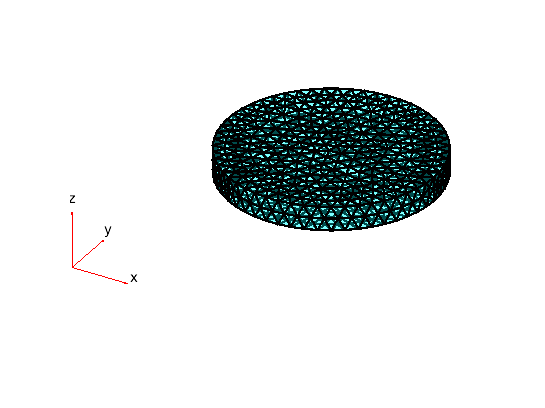

pdemesh(Estat_model,'FaceAlpha',.3)

The sizing of the mesh and geometery can be calculated by measuring the max distance between nodes in each direction. This value should be consistent with the dimensions of the geometry that was uploaded. 

% Measuring the dimesions of the mesh
xLength = max(Estat_model.Mesh.Nodes(1,:)) - min(Estat_model.Mesh.Nodes(1,:))

xLength = 0.0350

yLength = max(Estat_model.Mesh.Nodes(2,:)) - min(Estat_model.Mesh.Nodes(2,:))

yLength = 0.0350

zLength = max(Estat_model.Mesh.Nodes(3,:)) - min(Estat_model.Mesh.Nodes(3,:))

zLength = 0.0040


%Splitting components


## Parameters of the PDE & Governing Equations

### Parameters

These parameters are defined to represent the characteristics of the electrolyte solution and the material properties

% Relative Permeability
% epsilon_E = 100;
% epsilon_WE = 0;
% epsilon_RE = 0;
% 
% epsilon_S = 1E-8;
% epsilon_CM = .1;

%Conductivity
sigma_WE = 10000; %S/m
sigma_CE = 0;
sigma_RE = 0;

sigma_S = 100;
sigma_CM = 1.5; %S/m

% Dielectric Constant
epsilon_CE = 10000;
epsilon_WE = 10000;
epsilon_RE = 10000;

%epsilon_S = 2450;
%PHEMA
epsilon_S = 2.3;
epsilon_CM = 80; 



### Establish Time Domain of Simulation 

tlist = linspace(0,2,10);

### Define Conditions of the Numerical Simulation

Define conditions for the ion concentrations of the bulk material and the fluid medium. 

- Concentration of bound anionic groups

- Concentration of free cationic and anionic groups 

- Boundary conditions for the concentration near surfaces 

- Potential Values for electrodes

### First identify the relevant faces of the analysis on the geometry

pdegplot(gmModel,'CellLabels','on','FaceAlpha',.3);


Fluid_Cell = 1;
Fluid_Faces = cellFaces(gmModel,Fluid_Cell);
Fluid_Edges = cellEdges(gmModel,Fluid_Cell);

Scaffold_Cell = 2;
Scaffold_Faces = cellFaces(gmModel,Scaffold_Cell);
Scaffold_Edges = cellEdges(gmModel,Scaffold_Cell);

CE_Cell = 3;
CE_Faces = cellFaces(gmModel,CE_Cell);
CE_Edges = cellEdges(gmModel,CE_Cell);



% WE_Cell = 3;
% WE_Faces = cellFaces(gmModel,WE_Cell);
WE_Faces = [1376];
WE_Edges = [8,9];
% 
% RE_Cell = 4;
% RE_Faces = cellFaces(gmModel,RE_Cell);
% RE_Edges = cellEdges(gmModel,RE_Cell);

Plate_Faces = [1,2,3];
Plate_Edges = nan;


## Material Properties  

The materials of interest are the electrolyte medium or culture medium, scaffold polymer material and dopant, working electrode material.

First make necessary unit conversions to match the units expected from matlab

Define permeability and permittivity values as perscribed for the fluid volume.

%%Vacuum
Estat_model.VacuumPermeability = 1.2566370614E-6; %H/m (Henry per meter)
Estat_model.VacuumPermittivity = 8.8541878128E-12; %F/m (Farads per meter)

%%Culture Medium
electromagneticProperties(Estat_model,"Cell", ...
    Fluid_Cell,"RelativePermittivity",epsilon_CM,"Conductivity",sigma_CM)

ans =   ElectromagneticMaterialAssignment with properties:

              RegionType: 'Cell'
                RegionID: 1
    RelativePermittivity: 80
    RelativePermeability: []
            Conductivity: 1.5000


% %%Working Electrode
% electromagneticProperties(Estat_model,"Cell", ...
%     WE_Cell,"RelativePermittivity",epsilon_E,"Conductivity",sigma_WE)
%%Counter Electrode
electromagneticProperties(Estat_model,"Cell", ...
    CE_Cell,"RelativePermittivity",epsilon_CE,"Conductivity",sigma_CE)

ans =   ElectromagneticMaterialAssignment with properties:

              RegionType: 'Cell'
                RegionID: 3
    RelativePermittivity: 10000
    RelativePermeability: []
            Conductivity: 0


% %Reference Electrode
% electromagneticProperties(Estat_model,"Cell", ...
%     RE_Cell,"RelativePermittivity",epsilon_RE,"Conductivity",sigma_RE)


%Scaffold
electromagneticProperties(Estat_model,"Cell", ...
    Scaffold_Cell,"RelativePermittivity",epsilon_S,"Conductivity",sigma_S)

ans =   ElectromagneticMaterialAssignment with properties:

              RegionType: 'Cell'
                RegionID: 2
    RelativePermittivity: 2.3000
    RelativePermeability: []
            Conductivity: 100


## Boundary Conditions

In the pHEMA paper the conductivity of these scaffolds was tested using a custome ITO dual electrode setup. The boundary conditions of the faces that make contact with this electrode setup are set to be constant voltages.

% Potential Values
Plate_Voltage = 0;
WE_Voltage = .8;
CE_Voltage = 0;
RE_Voltage = 0;

%%Well Wall Conditions
% electromagneticBC(Estat_model,'Face',Plate_Faces,'Voltage',Plate_Voltage)

%%Electrode Conditions
electromagneticBC(Estat_model,'Face',WE_Faces,'Voltage',WE_Voltage)

ans =   ElectromagneticBCAssignment with properties:

    MagneticPotential: []
             RegionID: 1376
           RegionType: 'Face'
           Vectorized: 'off'
              Voltage: 0.8000


%electromagneticBC(Estat_model,'Edge',WE_Faces,'Voltage',WE_Voltage)

%%Counter Electrode Conditions
 electromagneticBC(Estat_model,'Face',CE_Faces,'Voltage',CE_Voltage)

ans =   ElectromagneticBCAssignment with properties:

    MagneticPotential: []
             RegionID: [183 187 197]
           RegionType: 'Face'
           Vectorized: 'off'
              Voltage: 0



% %%Fluid Conditions
% electromagneticBC(Estat_model,'Face',_Faces,'Voltage',Electrode_Face_Voltage)

% %%RE Conditions
% electromagneticBC(Estat_model,'Face',RE_Faces,'Voltage',RE_Voltage)

## Charge Density

%% Charge Densities
WE_CD = 2.6E-5;
CE_CD = 0;
RE_CD = 0;
%S_CD = 2.5E-5;
F_CD = 15E-7;

%% Current Densities
% WE_CD = 4.6;
% CE_CD = 0;
% RE_CD = 0;
% S_CD = 0;
% F_CD = 0;

%% Working Electrode
%electromagneticSource(Estat_model,"Cell", Scaffold_Cell, "ChargeDensity",WE_CD);

% %% Counter Electrode
% electromagneticSource(Estat_model,"Cell",CE_Cell, "ChargeDensity",WE_CD);

% %% Fluid
%electromagneticSource(Estat_model,"Cell",Fluid_Cell, "ChargeDensity",F_CD);

% %% Refference Electrode
% electromagneticSource(Estat_model,"Cell",Scaffold_Cell, "ChargeDensity",WE_CD);

% %% Scaffold
% electromagneticSource(Estat_model,"Cell",Scaffold_Cell, "ChargeDensity",S_CD);

## Solving the Model

emagmodel = Estat_model;
R = solve(emagmodel);
model = emagmodel;

## Visualizing Model Results

### Selecting Subdomains for Plotting

pdegplot(gmModel,'CellLabels','on','FaceAlpha',.3);


S_mesh = findElements(model.Mesh,"Region","Cell",Scaffold_Cell);
F_mesh = findElements(model.Mesh,"Region","Cell",Fluid_Cell);
CE_mesh = findElements(model.Mesh,"Region","Cell",CE_Cell);
% WE_mesh = findElements(model.Mesh,"Region","Cell",WE_Cell);
% RE_mesh = findElements(model.Mesh,"Region","Cell",RE_Cell);

### Electric Potential Plot

Plot of the electric field and distribuiton throughout the geometery. Be sure to adjust opacity of the plot to see features.

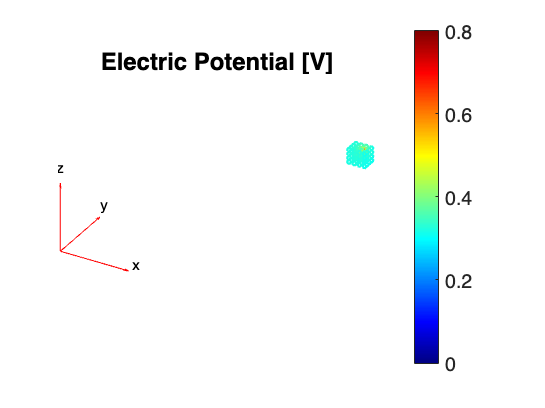

%Scaffold
pdeplot3D(model.Mesh.Nodes, ...
          model.Mesh.Elements(:,S_mesh), ...
          "ColorMapData",R.ElectricPotential);

title('Electric Potential [V]')
xlabel('x')
ylabel('y')
zlabel('z')
axis equal

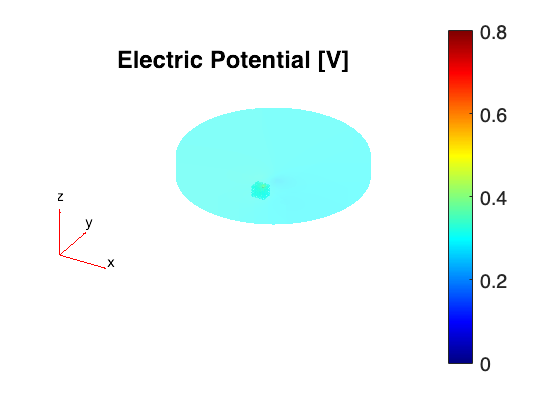


%Fluid
pdeplot3D(model.Mesh.Nodes, ...
          model.Mesh.Elements(:,F_mesh), ...
          "ColorMapData",R.ElectricPotential,"FaceAlpha",.3);

title('Electric Potential [V]')
xlabel('x')
ylabel('y')
zlabel('z')
axis equal

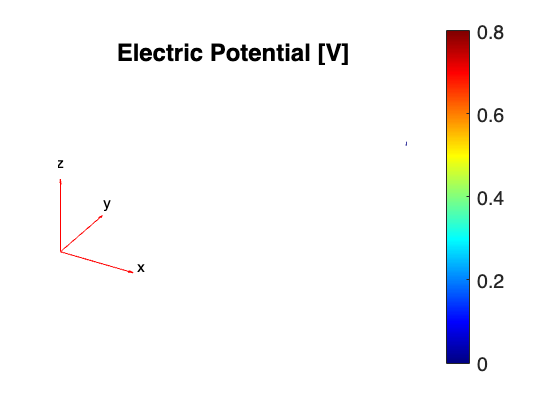


%CE & RE
pdeplot3D(model.Mesh.Nodes, ...
          model.Mesh.Elements(:,CE_mesh), ...
          "ColorMapData",R.ElectricPotential);

title('Electric Potential [V]')
xlabel('x')
ylabel('y')
zlabel('z')
axis equal


% pdeplot3D(model.Mesh.Nodes, ...
%           model.Mesh.Elements(:,RE_mesh), ...
%           "ColorMapData",R.ElectricPotential,"FaceAlpha",.5);
% 
% title('Voltage [V]')
% xlabel('x')
% ylabel('y')
% zlabel('z')
% axis equal

### Electric Field Plot 

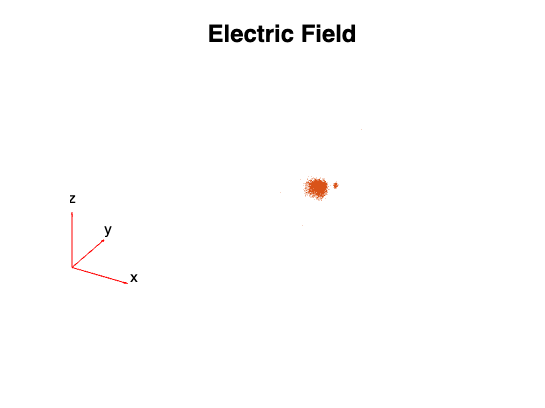

%Scaffold 
pdeplot3D(model.Mesh.Nodes, ...
          model.Mesh.Elements(:,S_mesh) ...
          ,"FlowData",[R.ElectricField.Ex ...
                                R.ElectricField.Ey ...
                                R.ElectricField.Ez])
axis equal

title('Electric Field')
xlabel('x')
ylabel('y')
zlabel('z')


%Fluid
pdeplot3D(model.Mesh.Nodes, ...
          model.Mesh.Elements(:,F_mesh) ...
          ,"FlowData",[R.ElectricField.Ex ...
                                R.ElectricField.Ey ...
                                R.ElectricField.Ez])

title('Electric Field')
axis equal
xlabel('x')
ylabel('y')
zlabel('z')

%CE
pdeplot3D(model.Mesh.Nodes, ...
          model.Mesh.Elements(:,CE_mesh) ...
          ,"FlowData",[R.ElectricField.Ex ...
                                R.ElectricField.Ey ...
                                R.ElectricField.Ez])

title('Electric Field')
axis equal
xlabel('x')
ylabel('y')
zlabel('z')

### Electric Flux Density Plot

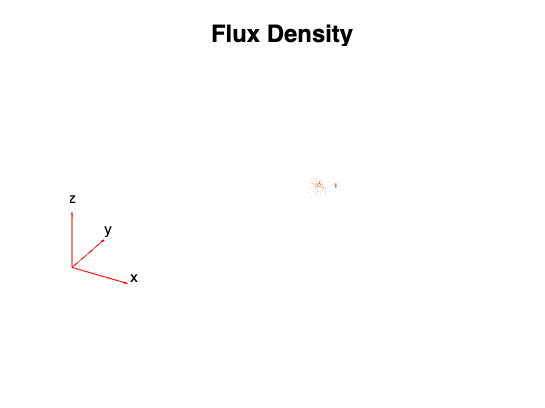

%Scaffold
pdeplot3D(model.Mesh.Nodes, ...
          model.Mesh.Elements(:,S_mesh), ...
          "FlowData",[R.ElectricFluxDensity.Dx ...
          R.ElectricFluxDensity.Dy ...
          R.ElectricFluxDensity.Dz],'Mesh','on',"FaceAlpha", 1)
title('Flux Density')
xlabel('x')
ylabel('y')
zlabel('z')
axis equal

%Fluid
pdeplot3D(model.Mesh.Nodes, ...
          model.Mesh.Elements(:,F_mesh), ...
          "FlowData",[R.ElectricFluxDensity.Dx ...
          R.ElectricFluxDensity.Dy ...
          R.ElectricFluxDensity.Dz],'Mesh','on')
title('Flux Density')
xlabel('x')
ylabel('y')
zlabel('z')
axis equal



%Electrodes
pdeplot3D(model.Mesh.Nodes, ...
          model.Mesh.Elements(:,CE_mesh), ...
          "FlowData",[R.ElectricFluxDensity.Dx ...
          R.ElectricFluxDensity.Dy ...
          R.ElectricFluxDensity.Dz])
title('Flux Density')
xlabel('x')
ylabel('y')
zlabel('z')
axis equal